# 診断特徴デザイナーを用いた特徴抽出と機械学習による異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

診断特徴デザイナーの活用に関しては以下のページをご参照ください。

[https://jp.mathworks.com/help/predmaint/ug/analyze-and-select-features-for-pump-diagnostics.html](https://jp.mathworks.com/help/predmaint/ug/analyze-and-select-features-for-pump-diagnostics.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Predictive Maintenance Toolbox™

- System Identification Toolbox™

- Statistics and Machine Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

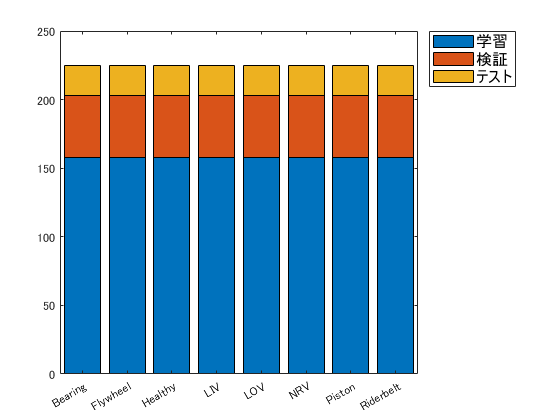

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## 可視化

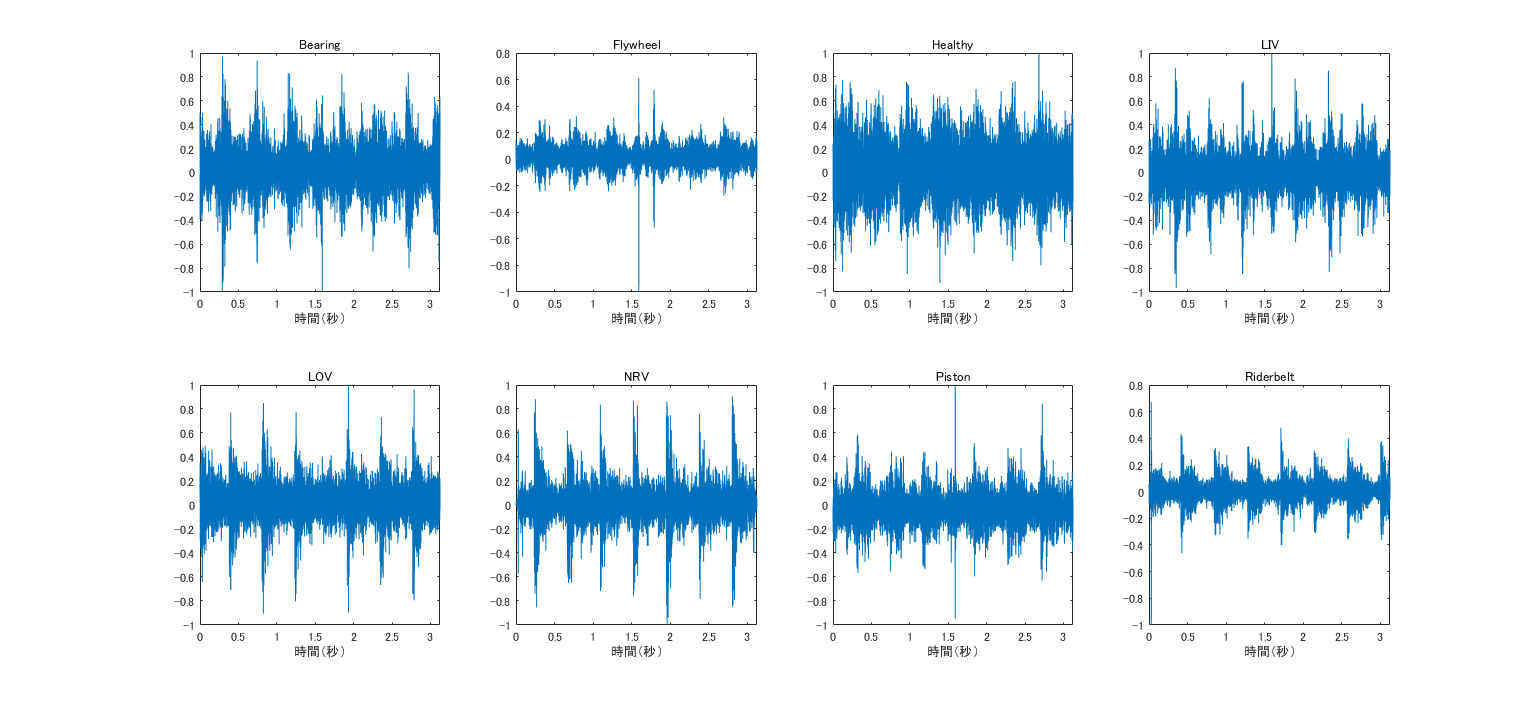

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## 学習用

trainFeatures = [];
trainLabels = adsTrain.Labels;
reset(adsTrain);

measNumber = size(adsTrain.Files,1); %* 計測回数

%* 作成データの初期化
sz = [measNumber,3];
varTypes = {'cell','string','string'};
varNames = {'data','faultCode','FileID'};
trainData = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

trainData.faultCode = adsTrain.Labels;

tic
for k = 1:height(adsTrain.Files)
    [audioIn,fileInfo] = read(adsTrain);
    
    filename = adsTrain.Files{k};
    [filepath,name,ext] = fileparts(filename);
    
    tt = array2timetable(audioIn,"SampleRate",fs);        
    
    %* timetable変数をtable変数に代入
    trainData.data(k) = {tt};
    trainData.FileID(k) = string([name,ext]);
end
toc

経過時間は 12.753588 秒です。


## 検証用

validationFeatures = [];
validationLabels = adsValidation.Labels;
reset(adsValidation);

%* 作成データの初期化
sz = [height(adsValidation.Files),3];
varTypes = {'cell','string','string'};
varNames = {'data','faultCode','FileID'};
validationData = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

validationData.faultCode = adsValidation.Labels;

tic
for k = 1:height(adsValidation.Files)
    [audioIn,fileInfo] = read(adsValidation);
    
    filename = adsValidation.Files{k};
    [filepath,name,ext] = fileparts(filename);
    
    tt = array2timetable(audioIn,"SampleRate",fs);        
    
    %* timetable変数をtable変数に代入
    validationData.data(k) = {tt};
    ValidationData.FileID(k) = string([name,ext]);
end
toc

経過時間は 2.964695 秒です。


## テスト用

testFeatures = [];
testLabels = adsTest.Labels;
reset(adsTest);

%* 作成データの初期化
sz = [height(adsTest.Files),3];
varTypes = {'cell','string','string'};
varNames = {'data','faultCode','FileID'};
testData = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

testData.faultCode = adsTest.Labels;

tic
for k = 1:height(adsTest.Files)
    [audioIn,fileInfo] = read(adsTest);

    filename = adsTest.Files{k};
    [filepath,name,ext] = fileparts(filename);
    
    tt = array2timetable(audioIn,"SampleRate",fs);        
    
    %* timetable変数をtable変数に代入
    testData.data(k) = {tt};
    testData.FileID(k) = string([name,ext]);
end
toc

経過時間は 1.283159 秒です。


## データの保存

% save featureTable_diagnosticFeatureDesignerML.mat trainData validationData testData % データの保存

## 診断特徴デザイナー（作業時間：マニュアルで約10分）

特徴抽出の過程は以下のビデオも参考になります。（動画05:40前後から）：

[https://jp.mathworks.com/videos/part-3-feature-extraction-for-predictive-maintenance-1545052389165.html](https://jp.mathworks.com/videos/part-3-feature-extraction-for-predictive-maintenance-1545052389165.html)

上記の予知保全ビデオシリーズは全5編となります。ぜひご覧ください。

diagnosticFeatureDesigner

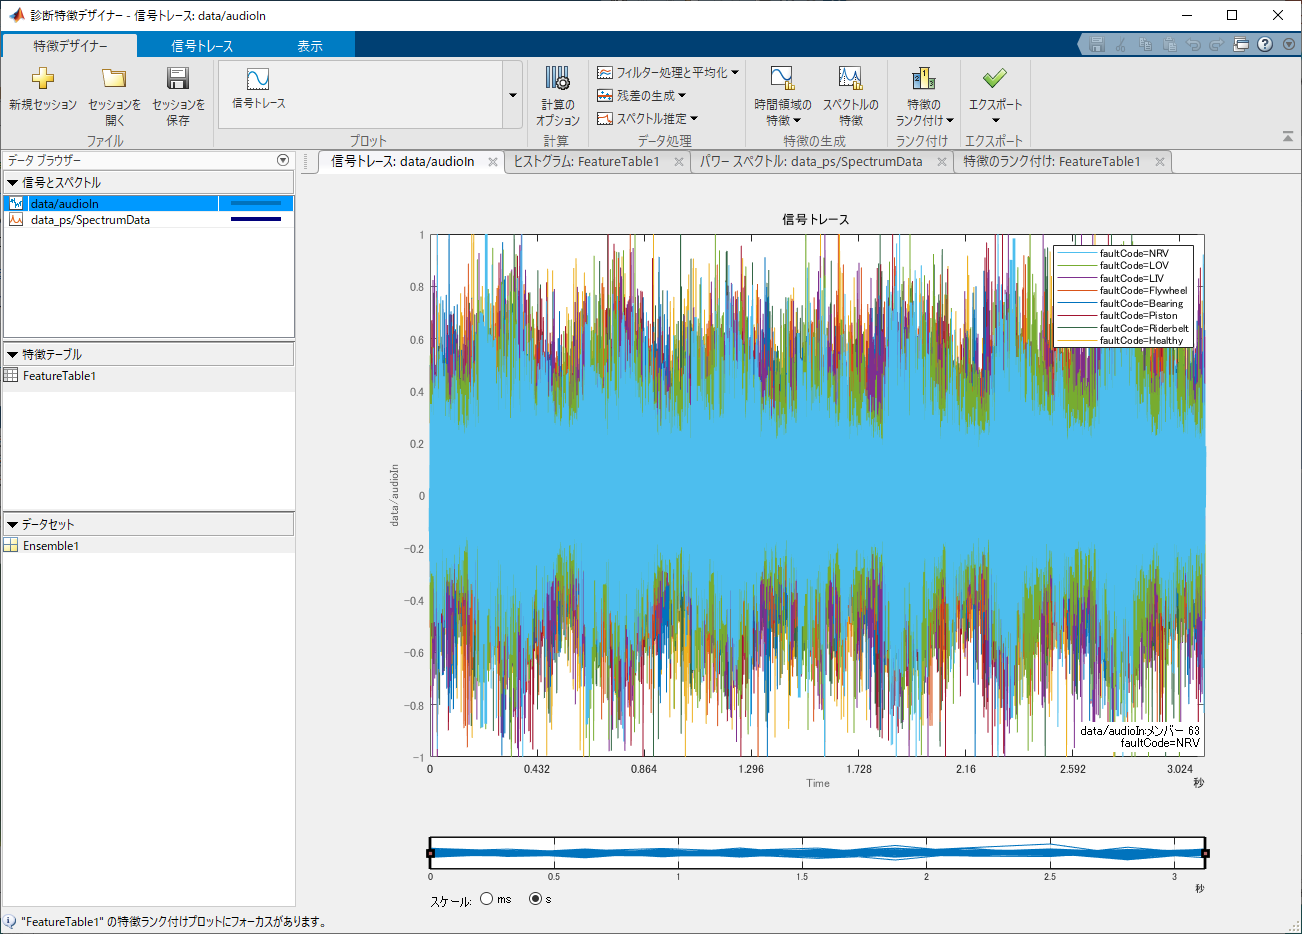

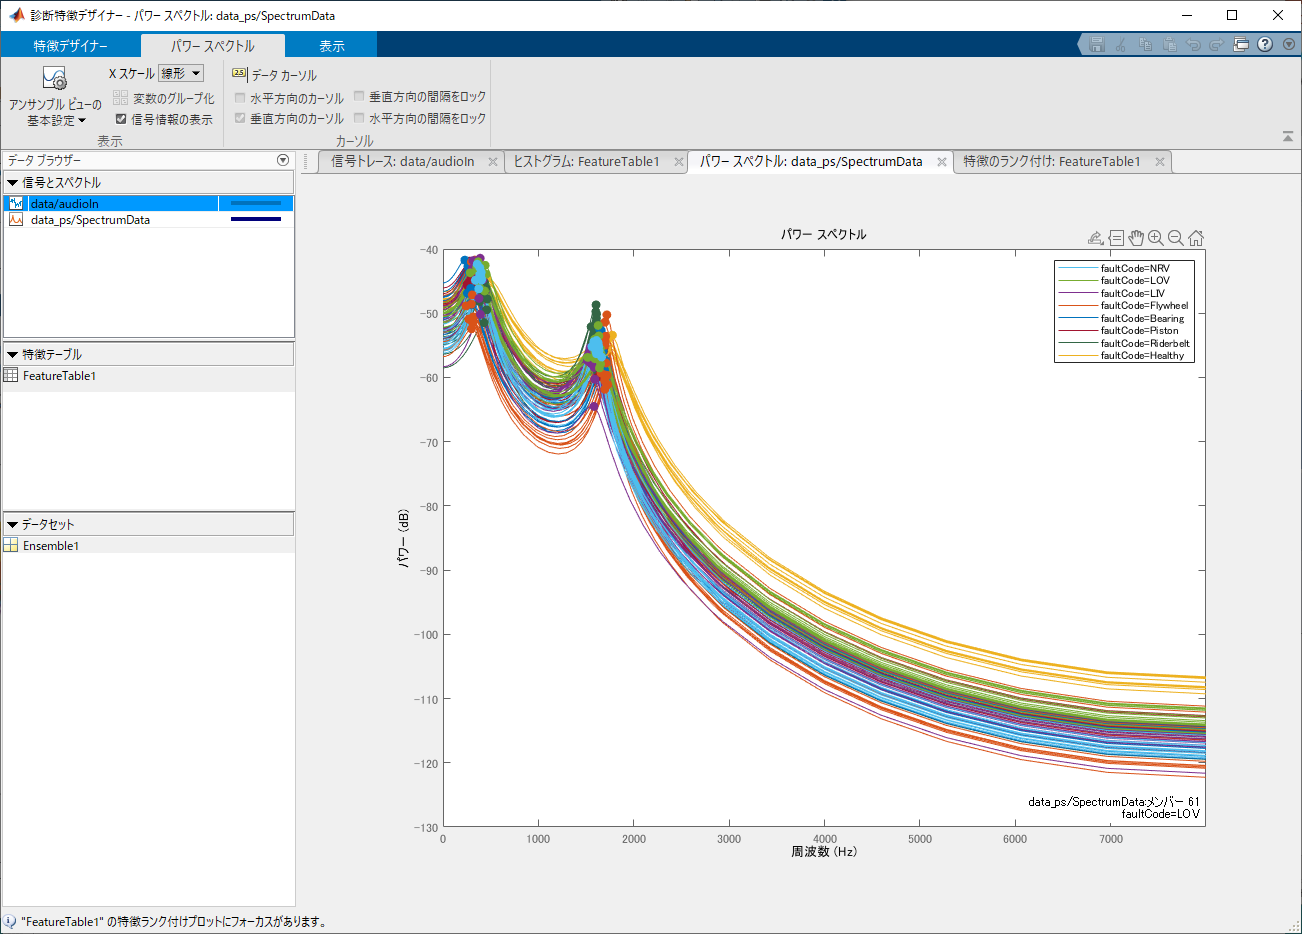

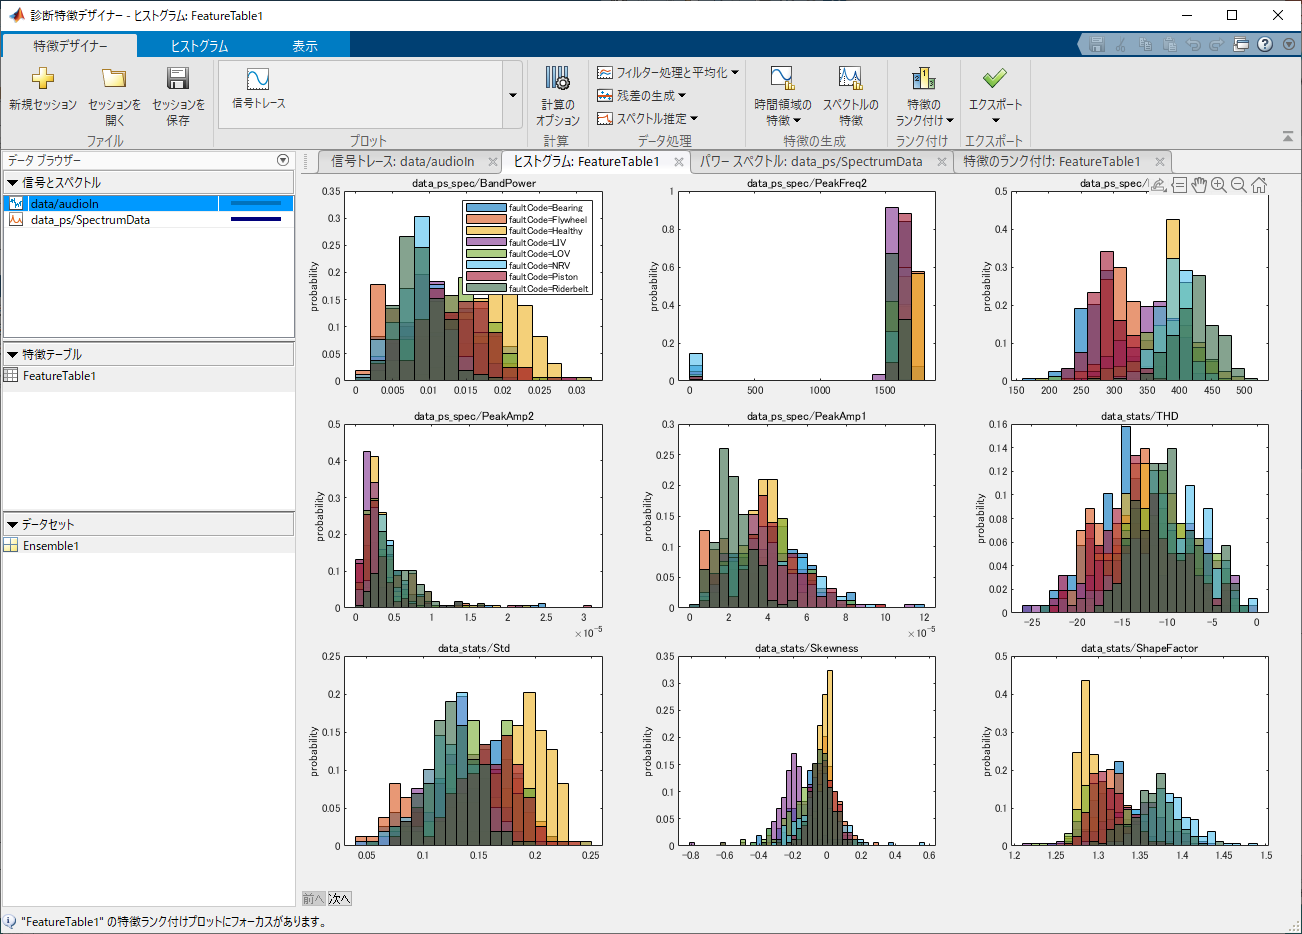

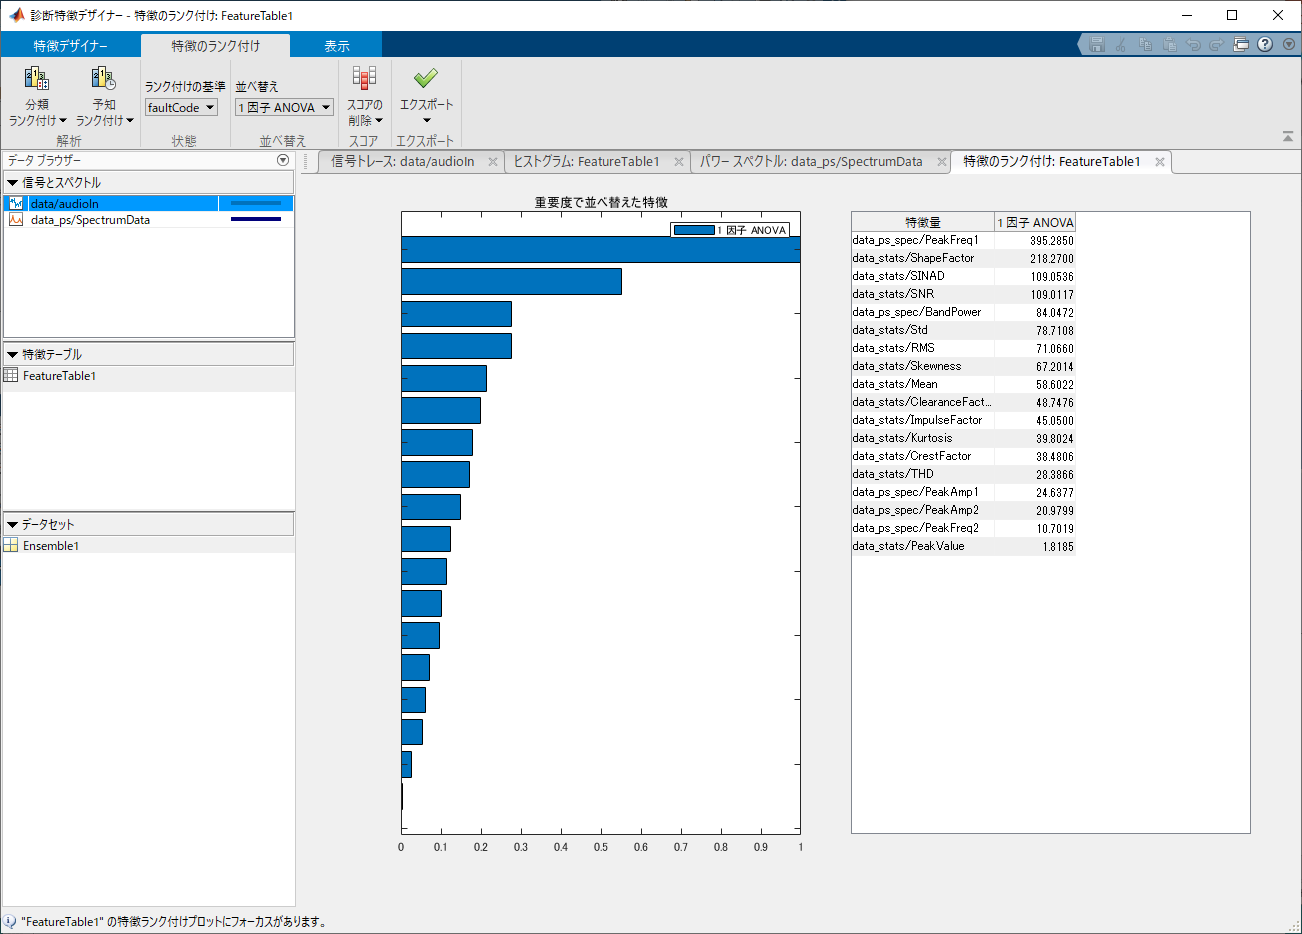

## MATLABコード生成による特徴量の抽出（診断特徴デザイナー⇒エクスポート⇒次の関数を生成⇒関数の生成）

診断特徴デザイナーの「マニュアルの」特徴抽出をMATLABコード生成により「自動化」

% 学習用
tic
[trainTbl,~,~] = diagnosticFeatures(trainData)
toc
% テスト用
tic
[testTbl,~,~] = diagnosticFeatures(testData)
toc

## 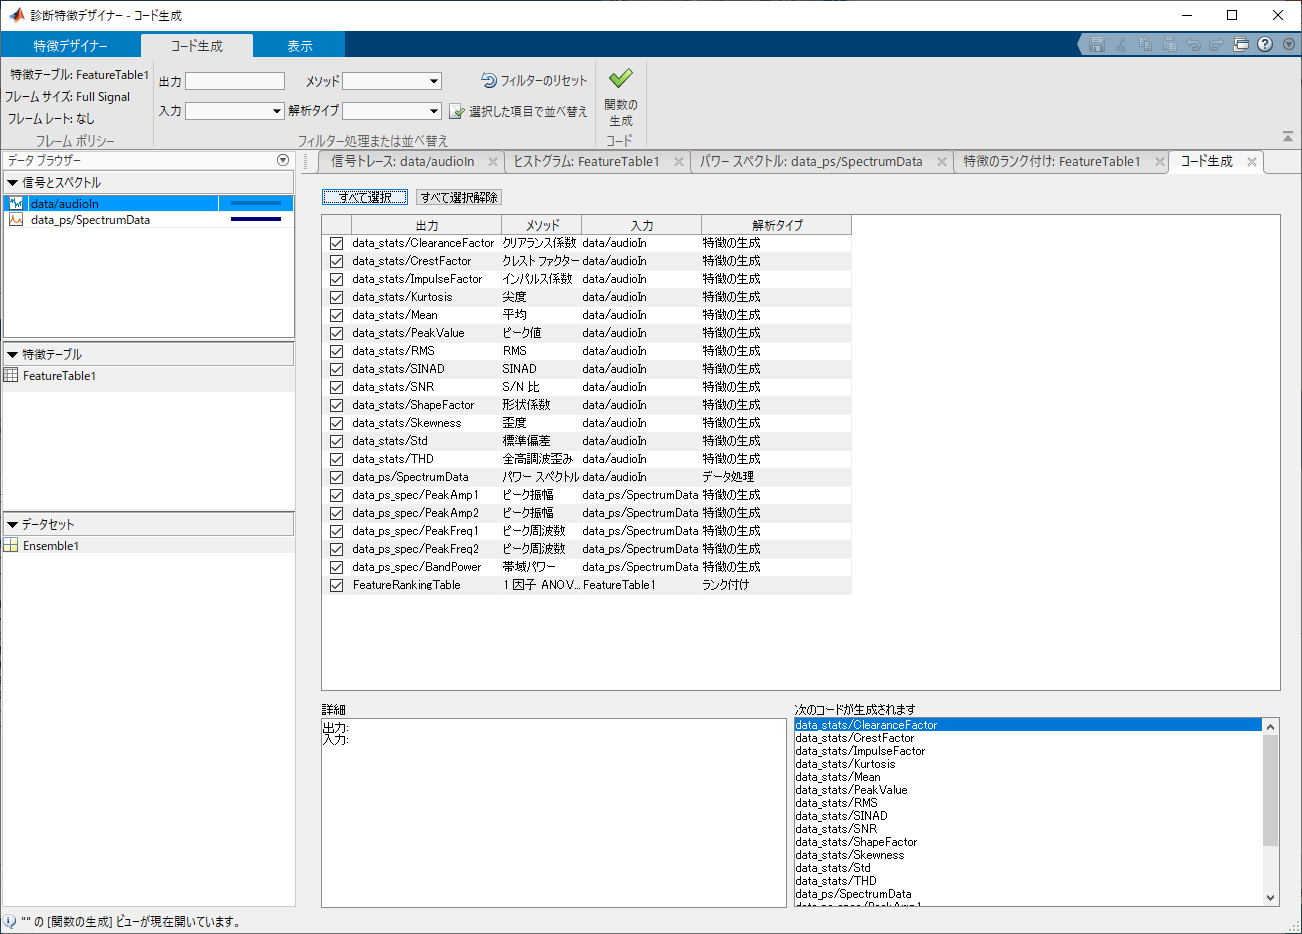

## データの保存

% save featureTableDiagnosticFeatureDesignerApp.mat trainTbl testTbl trainLabels testLabels % データの保存

## 分類学習器（作業時間：約2分。多クラス分類：29種類の機械学習の自動作成）

約85%の精度。

分類学習器は、診断特徴デザイナーの「エクスポート⇒特徴を分類学習器にエクスポートします」から起動できます。

分類学習器を直接起動される場合は、trainTbl を入力データとしてアプリ内にインポートしてください。

trainTblは以下のコマンドより読み込むことが出来ます。

classificationLearner

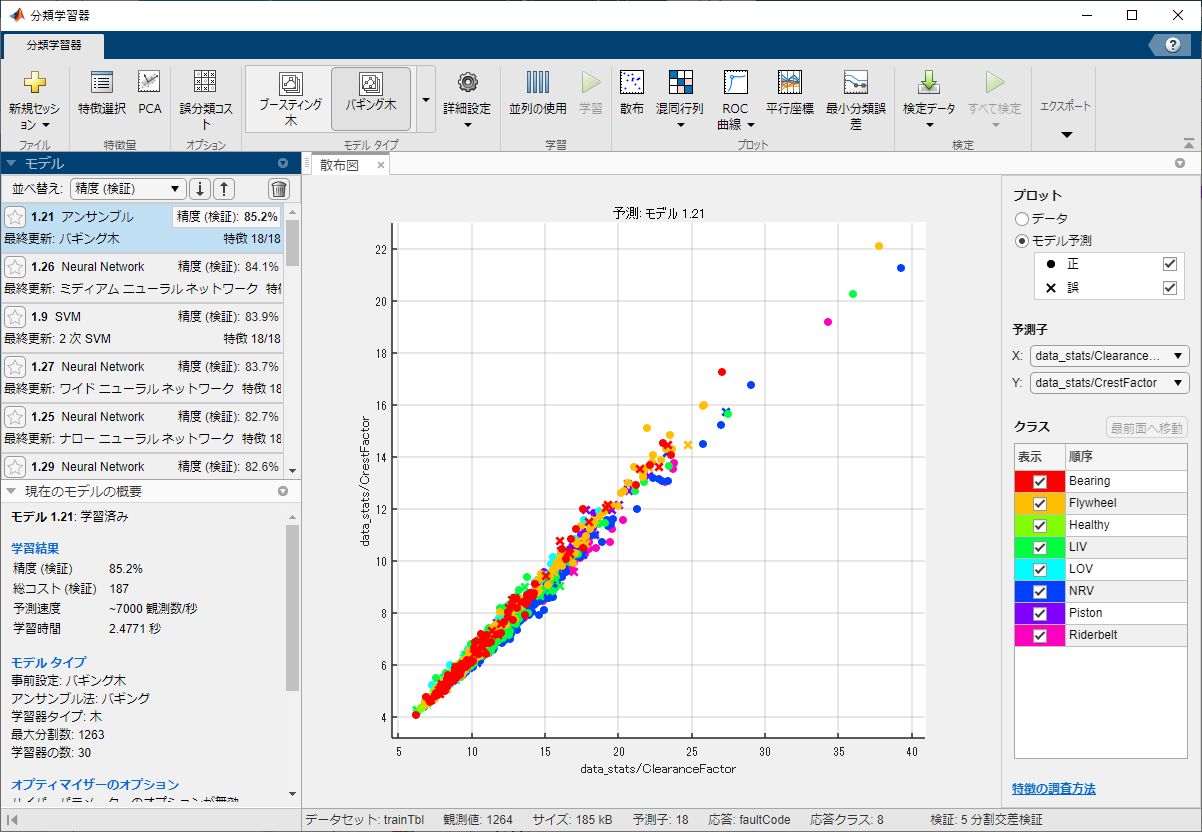

## テスト：精度検証

rng('default');

trainTbl = 1264×19 table
    faultCode    data_stats/ClearanceFactor    data_stats/CrestFactor    data_stats/ImpulseFactor    data_stats/Kurtosis    data_stats/Mean    data_stats/PeakValue    data_stats/RMS    data_stats/SINAD    data_stats/SNR    data_stats/ShapeFactor    data_stats/Skewness    data_stats/Std    data_stats/THD    data_ps_spec/PeakAmp1    data_ps_spec/PeakAmp2    data_ps_spec/PeakFreq1    data_ps_spec/PeakFreq2    data_ps_spec/BandPower
    _________    __________________________    ______________________    ________________________    ___________________    _______________    ____________________    ______________    ________________    ______________    ______________________    ___________________    ______________    ______________    _____________________    _____________________    ______________________    ______________________    ______________________
    Healthy                7.8405                      5.1681                     6.5854                   3.

[trainedClassifier, testAccuracy] = trainClassifier(trainTbl)

経過時間は 283.232608 秒です。


predLabels = trainedClassifier.predictFcn(testTbl);
accuracy = 100*sum(predLabels == testLabels) / numel(testLabels) % 精度（%）

figure; clf;

testTbl = 176×19 table
    faultCode    data_stats/ClearanceFactor    data_stats/CrestFactor    data_stats/ImpulseFactor    data_stats/Kurtosis    data_stats/Mean    data_stats/PeakValue    data_stats/RMS    data_stats/SINAD    data_stats/SNR    data_stats/ShapeFactor    data_stats/Skewness    data_stats/Std    data_stats/THD    data_ps_spec/PeakAmp1    data_ps_spec/PeakAmp2    data_ps_spec/PeakFreq1    data_ps_spec/PeakFreq2    data_ps_spec/BandPower
    _________    __________________________    ______________________    ________________________    ___________________    _______________    ____________________    ______________    ________________    ______________    ______________________    ___________________    ______________    ______________    _____________________    _____________________    ______________________    ______________________    ______________________
    LIV                    10.476                      6.2731                     8.5355                   5.94

confusionchart(testLabels, predLabels,"Normalization","row-normalized")

経過時間は 39.042763 秒です。


## 精度の可視化

trainedClassifier = フィールドをもつ struct :
                predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
         RequiredVariables: {1×18 cell}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationBaggedEnsemble]
                     About: 'この構造体は、分類学習器 R2021a からエクスポートされた学習済みのモデルです。'
              HowToPredict: '新しいテーブル T についての予測を行うには、次を使用します: ↵ yfit = c.predictFcn(T) ↵'c' をこの構造体の変数の名前 ('trainedModel' など) に置き換えます。 ↵ ↵テーブル T は次によって返される変数を含んでいなければなりません: ↵ c.RequiredVariables ↵変数形式 (行列/ベクトル、データ型など) は元の学習データと一致しなければなりません。 ↵追加の変数は無視されます。 ↵ ↵詳細については、How to predict using an exported model を参照してください。'

testAccuracy = 0.8457

accuracy = 85.7955

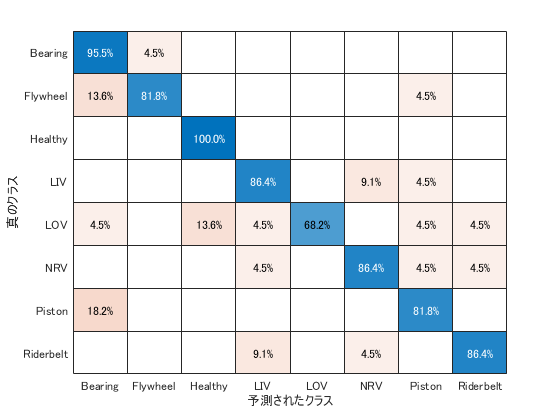

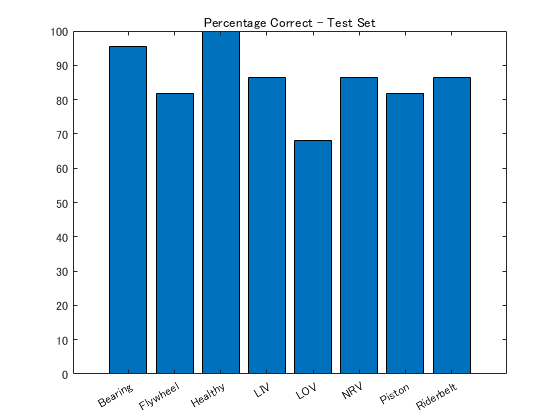

cm = confusionmat(testLabels, predLabels);
genreAccuracy = diag(cm)./tblTest.Count*100;
figure; clf;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*